# Riemann Sums

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

One of the most important and useful concepts of calculus is the idea of computing accumulation. In many situations, there is information about a rate of change (e.g., acceleration, velocity, concentration, flow, power) and calculus presents tools for calculating the accumulation that occurs (e.g., velocity, position, amount, volume, energy, etc.). 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

## Calculating Solar Energy Generation

### Background

Consider the power generated by a fixed solar array with a maximum rated output of 643.545 kW. To convert this power (in kilowatts) into energy (kilowatt-hours) requires accumulating this power over time. 

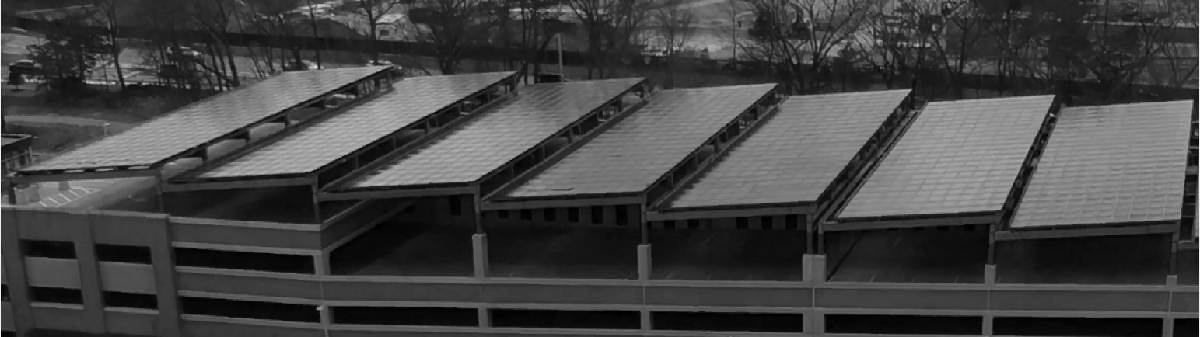

Data from the MathWorks Lakeside Campus parking garage solar array, March 14-20, 2021. 

figure;           % Initialize a figure

% Load solar power generation data and preprocess to track time
Data = readtable("SolarPowerGeneration.csv","DateLocale","en_US");
Data.Timestamp(1);
Data.Timestamp = Data.Timestamp-Data.Timestamp(1);

% Plot the data and label the graph and axes
plot(days(Data.Timestamp), Data.AC_kw)
title("Power Generation, March 14-20 2021")
xticks(.5:1:6.5)
xticklabels(["Day 1" "Day 2" "Day 3" "Day 4" "Day 5" "Day 6" "Day 7"])
xlabel("Time since 00:00, March 14, 2021 (days)")
ylabel("Power in kilowatts (kw)")
 

#### Select a day

Choose a day to analyze more carefully.

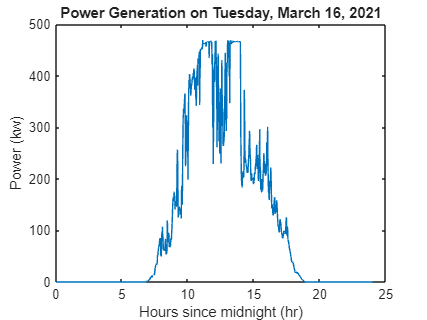

DesiredDay = 3;              
% Use a try/catch block to fail gracefully if the sections are run out of
% order. Alternately, this could include live controls that run this
% section and any modified or not yet run sections above
try 
    [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(DesiredDay,Data);   % Check if the data is loaded
catch
    % If the data set is not yet loaded, do so here
    disp("You must load the data before you can analyze it.")
    disp("Loading data now ... to plot the full dataset, click the 'Load and Plot Data' button, above.")
    Data = readtable("SolarPowerGeneration.csv","DateLocale","en_US");
    Data.Timestamp(1);
    Data.Timestamp = Data.Timestamp-Data.Timestamp(1);
    disp("Data loaded, proceeding with analysis...")
    [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(DesiredDay,Data);
end

% Plot the selected data for the single day and label the graph and axes
% Include a special note for the exceptionally short day due to the time
% change to EDT from EST on March 14, 2021
figure
plot(DataHours,DataPower)
title("Power Generation on "+StrDay+", March "+DateDay+", 2021")
if DesiredDay == 1
    subtitle("Note the 23 hour day because of the time zone change")
end
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")

Focus on the period when it wasn't dark, so the panels had a chance of generating electricity.

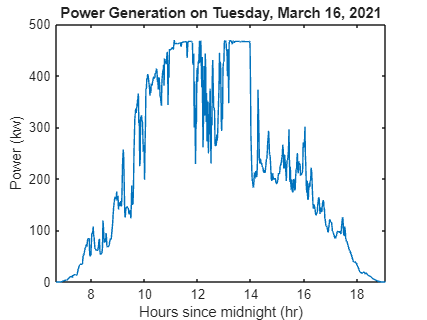

% Eliminate the leading and trailing 0's by restricting to times
% approximating sunrise and sunset
figure;
p1 = plot(DataHours(Sunrise:Sunset),DataPower(Sunrise:Sunset));
xlim([6+2/3 19+1/12])
title("Power Generation on "+StrDay+", March "+DateDay+", 2021")
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")

### Continuity of Datasets

This graph looks continuous, but in fact it is linearly interpolated between each adjacent datapoint, generated by sensor reports every minute across the day. Consider the scatterplot representation:

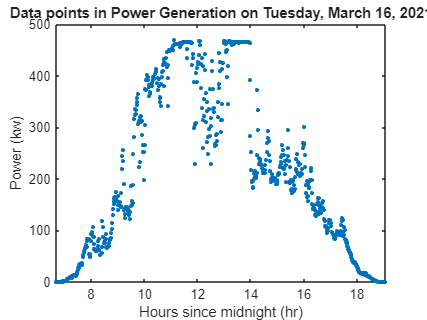

% Plot the data as discrete points to observe the scatter values
figure
p2 = plot(DataHours(Sunrise:Sunset),DataPower(Sunrise:Sunset),".","MarkerSize",9);
xlim([6+2/3 19+1/12])
title("Data points in Power Generation on "+StrDay+", March "+DateDay+", 2021")
if DesiredDay == 1
    subtitle("Note the 23 hour day because of the time zone change")
end
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")

 **Reflect**

- How easy is it to fit a simple curve to this data? Does it matter which day of the week is chosen?

- Are most real-world datasets continuous or discrete? Why? What implications does this have for using calculus in applications?

- Is the underlying data in this situation, where solar panels are generating power, continuous or discrete?

## Application: Riemann Sums with Rectangular Approximations

This data provides sensor readings at one minute time slices across the entire day. To calculate an approximation of the amount of energy generated, it is necessary to add up an approximation of the power generated in each time slice by the length of the time slice. Visually, if we select a left-endpoint approximation:

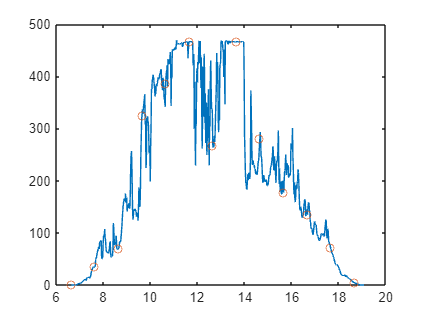

% Check to see if the data is loaded in the workspace, and if not load it 
% for a default day of Tuesday, March 16, 2021, without displaying errors
if ~exist("Sunrise","var")              % If a day is not chosen, use desiredday = 3 by default
    try
        [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(3,Data);
    catch
        disp("You must load the data before you can analyze it.")
        disp("Loading data now ... to plot the full dataset, return to the beginning of the file.")
%         rootDir = fileparts(mfilename('fullpath'))
        Data = readtable("SolarPowerGeneration.csv","DateLocale","en_US");
        Data.Timestamp(1);
        Data.Timestamp = Data.Timestamp-Data.Timestamp(1);
        disp("Data loaded, proceeding with analysis on Tuesday, March 16, 2021...")
        [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(3,Data);
    end
end

% Initialize parameters
Energy = 0;     % generated energy (kWh)      
dt = 1/60;      % minimal data step size (hours)
End0 = length(DataHours(Sunrise:Sunset));
% Set up the interval length in multiples of the minimal step size
Skip = 60;
% Select the Riemann sum method of value approximation
EndPt = "left";     
% Graph the output approximation overlaid on the data
figure
plot(DataHours(Sunrise:Sunset),DataPower(Sunrise:Sunset));
hold on
plot(DataHours(Sunrise:Skip:Sunset),DataPower(Sunrise:Skip:Sunset),"o")

for k = Sunrise:Skip:Sunset
    xval = DataHours(k);
    if EndPt == "midpoint"
        if mod(Skip,2)==1
            % If the data is known at the midpoint of the interval, use it
            Height = DataPower(k+(Skip+1)/2);
        else
            % If the data is not known, use linear interpolation to
            % estimate an appropriate value between the two nearest points
            Height = mean([DataPower(k+Skip/2) DataPower(k+Skip/2+1)]);
        end
    elseif EndPt == "left"
        % Select the left endpoint of the interval 
        Height = DataPower(k);
    elseif EndPt == "right"
        % Select the right endpoint of the interval
        Height = DataPower(k+Skip);
    end
    % Draw the rectangle on the plot
    rectangle("Position",[xval 0 Skip*dt Height],"EdgeColor","r");
    % Add the approximated energy generated in this interval to the total
    Energy = Energy+Skip*dt*Height;
end
if EndPt == "midpoint"
    % Add black stars marking the midpoint values of each interval
    DesiredPts = Sunrise:Skip:Sunset-Skip;
    if mod(Skip,2) == 1
        % If the data is known at the midpoint of the interval, use it
        plot(DataHours(DesiredPts)+(Skip/2)*dt,DataPower(DesiredPts+(Skip+1)/2),"k*","MarkerSize",8)
    elseif mod(Skip,2) == 0
        % If the data is not known, use linear interpolation to
        % estimate an appropriate value between the two nearest points
        plot(DataHours(DesiredPts)+(Skip/2)*dt,(DataPower(DesiredPts+Skip/2)...
            +DataPower(DesiredPts+Skip/2+1))/2,"k*","MarkerSize",8)
    end
end
title("Energy Generation on "+StrDay+", March "+DateDay+", 2021")
subtitle("Estimated energy generated = "+Energy+"kwh, "+EndPt+" approximation")
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")
hold off

Notice that many of these rectangles are overestimating (or underestimating) the value of the energy generated over that slice of time. 

  **Try**. By default, this plot is generated with a step size of 1 hour (60 minutes) and uses the left-endpoint to approximate the power generated over the entire interval. Try selecting both the right-endpoint approximation and the midpoint approximation as well as shortening the step size.

 **Reflect**.

- Which method (left-endpoint, right-endpoint, or midpoint) generates the most accurate approximation to the total energy generated?

- What impact does shortening the step size have on the total energy estimate? Does it matter whether it is using a left-endpoint, right-endpoint, or midpoint approximation?

#### Visualizing Error in Riemann Sum Approximations

Visualizing the error at each step requires tracking how much over-estimation and under-estimation contributes to each estimate. The red area visualizes the overestimation of energy production, while green area visualizes the underestimation of energy production.

% Check to see if the data is loaded in the workspace, and if not load it 
% for a default day of Tuesday, March 16, 2021, without displaying errors
if ~exist("Sunrise","var")              % If a day is not chosen, use desiredday = 3 by default
    try
        [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(3,Data);
    catch
        disp("You must load the data before you can analyze it.")
        disp("Loading data now ... to plot the full dataset, return to the beginning of the file.")
        Data = readtable("SolarPowerGeneration.csv","DateLocale","en_US");
        Data.Timestamp(1);
        Data.Timestamp = Data.Timestamp-Data.Timestamp(1);
        disp("Data loaded, proceeding with analysis on Tuesday, March 16, 2021...")
        [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(3,Data);
    end
end
dt = 1/60;   % minimal data step size (hours)

% Select the method of Riemann sum approximation
EndPt = "Left";   
MinSkip = 1;
for Skip=60:-1:MinSkip
    % Create 60 plots as individual frames showing how decreasing the step
    % size of "Skip" impacts the estimate of the energy generated
    Energy = 0;
    plot(DataHours(Sunrise:Sunset),DataPower(Sunrise:Sunset));
    hold on
    for k = Sunrise:Skip:Sunset
        xval = DataHours(k);
        if EndPt == "Midpoint"
            if mod(Skip,2)==1
                % Choose the midpoint value, if known
                Height = DataPower(k+(Skip+1)/2);
            else
                % Interpolate the midpoint value between adjacent known
                % values
                Height = mean([DataPower(k+Skip/2) DataPower(k+Skip/2+1)]);
            end
        elseif EndPt == "Left"
            % Select the left endpoint value for the interval
            Height = DataPower(k);
        elseif EndPt == "Right"
            % Select the right endpoint value for the interval
            Height = DataPower(k+Skip);
        elseif EndPt == "Maximum"
            % Select the maximum known value over the interval
            Height = max(DataPower(k:k+Skip));
        elseif EndPt == "Minimum"
            % Select the minimum known value over the interval
            Height = min(DataPower(k:k+Skip));
        end
        % Plot the rectangular approximation using a maximally contrasting
        % color for either a dark or light background
        fig = gcf;
        MaxContastColor = round(1-fig.Color);
        rectangle("Position",[xval 0 Skip*dt Height],"EdgeColor",MaxContastColor);
        Energy = Energy+Skip*dt*Height;
        % Plot the over- or under-estimate in different colors
        ViewRiemannBetween(DataHours(k:k+Skip),DataPower(k:k+Skip),Height)
    end
    title("Estimated Energy Generation of "+Energy+" kwh on "+StrDay+", March "+DateDay+", 2021")
    if Skip > 1
        subtitle(EndPt+" endpoint approximation, step = "+Skip+" minutes")
    else
        subtitle(EndPt+" endpoint approximation, step = "+Skip+" minute")
    end
    xlabel("Hours since midnight (hr)")
    ylabel("Power (kw)")
    hold off
    WaitTime = 0.2;
    pause(WaitTime);
    drawnow
end

  **Try**.

- Change the method of approximation to right endpoint, midpoint, maximum value, and minimum value.

- Change the day of the week that you are studying.

- Use the slider or watch the animation to observe the impact of increasing/decreasing the step size.

 **Reflect**.

- What do you notice about the error for the different approximation methods? 

- What impact does shortening the step size have on the total energy estimate? Does it matter which type of estimate you are using? Why or why not?

## Riemann Sum with Trapezoidal Approximation

Constant value approximations are frequently clearly bad approximations, even to the naked eye. Continuing the theme of approximating functions by polynomials, after a constant (0th degree polynomial) the 1st degree polynomial approximation is a line. Using the endpoints of each interval this gives us a trapezoidal approximation of the area under the curve.

syms x
f(x) =  (x-5)*(x+2)*(x-7);
StepSize = 188; 
xVals = -5:.01:5;
fVals = f(xVals);
plot(xVals,fVals)
% fplot(f(x),[1 10],"k-","LineWidth",2)
hold on
SumTot = DisplayTrapezoidMethod(xVals,fVals,1,length(xVals),StepSize,.01);
title("Trapezoidal Method with step size "+StepSize*(xVals(2)-xVals(1)))
subtitle("")
hold off


### Application: Solar Energy Data

Compare using trapezoidal approximation on the solar energy data with different step sizes to the best possible estimate given the resolution of the data.

 
% Compute and display the energy with varying step sizes from 1 hour down
% to 5 minutes using the trapezoidal approximation
Energy = DisplayTrapezoidMethod(DataHours,DataPower,Sunrise,Sunset,60:-5:5,1/60);
% Compute the best available energy estimate given the data
Height = (DataPower(Sunrise+1:Sunset)+DataPower(Sunrise:Sunset-1))/2;
Energy = [Energy;sum(Height*(1/60))];
% Create a new plot of the estimates of energy generation against step size
plot([60:-5:5 1],Energy)
hold on
% Add a line for the best estimate
yline(Energy(end),"r:")
title("Energy Generation Estimates compared to best")
xlabel("Step size (min)")
ylabel("Energy (kwh)")
legend(["Energy Estimate","Best Approximation"],"Location","northwest")
hold off


[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

The function `ChooseDay` returns the chosen timeslice of the overall data file.

function [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = ChooseDay(desiredDay,data)
% ChooseDay selects a specified slice of information from data
% Inputs: desiredDay, an integer corresponding to the day of the week
%         data, a time series data structure
% Outputs: dataHours, a time variable in hours
%          dataPower, corresponding AC production data in kilowatts 
%          sunrise, the index of approximate sunrise in dataHours
%          sunset, the index of approximate sunset in dataHours
%          strDay, a string giving the name of the weekday of desiredDay
%          dateDay, an integer giving the day of the month of desiredDay
dayoffset = 24*60;
if desiredDay == 1
    startday = 1;
    sunrise = 5.75*60;            % the missing hour is from the time change
    sunset = 18*60;
    endday = dayoffset-60;        % the missing hour is from the time change
else
    startday = (desiredDay-1)*dayoffset-59;
    sunrise = 6.75*60-5;
    sunset = 19*60+5;
    endday = desiredDay*dayoffset-60;
end
dataHours = (days(data.Timestamp(startday:endday))-(desiredDay-1))*24;
dataPower = data.AC_kw(startday:endday);
weekday = ["Sunday" "Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday"];
strDay = weekday(desiredDay);
dateDay = 13+desiredDay;
end

The function `ViewTrapBetween` sets up the trapezoidal approximation graphs.

function ViewTrapBetween(xdata,fdata,skip)
% ViewTrapBetween computes and draws a trapezoidal approximation to fdata
%     with a constant interval length of skip between xdata values
% Inputs: xdata is a vector of independent variable values
%         fdata is a vector of dependent variable values wrt xdata
%         skip is an integer 

fdata = reshape(fdata,[1 length(fdata)]); % make fdata a row vector
xdata = reshape(xdata,[1 length(xdata)]); % make xdata a row vector

% make a vector of the slope from the beginning to end of each interval
slopes = (fdata(1+skip:skip:end)-fdata(1:skip:end-skip))./(xdata(1+skip:skip:end)-xdata(1:skip:end-skip)); 

% expand the slope data to match the size of xdata with each point in the
% interval being matched to the slope for the entire interval
slopedata = reshape(slopes.*ones(skip,1),1,[]); % define vector of slopes at each value
if length(slopedata) < length(fdata)
    k = length(fdata)-length(slopedata);
    m = (fdata(end)-fdata(end-k))/(xdata(end)-xdata(end-k));
    restSlope = m.*ones(1,k);
    slopedata = [slopedata restSlope];
end

x0 = xdata(1:skip:end);                  % define center time value for tangent line
x0data = reshape(x0.*ones(skip,1),1,[]); % define associated center value for each point
y0 = fdata(1:skip:end);                  % define center height value for tangent line
y0data = reshape(y0.*ones(skip,1),1,[]); % define associated center value for each point

% Compute the heightdata corresponding to the piecewise linear
% approximation of fdata over intervals of length skip
heightdata = y0data(1:length(fdata)) + slopedata.*(xdata-x0data(1:length(fdata)));

% Plot the trapezoidal approximation for each interval and shade the extra
% (or missing, respectively) area red (or green). 
DrawColoredPolys(xdata,fdata,heightdata)
end

The function `ViewRiemannBetween` plots the signed between `fdata` and the line `y=height`.

function ViewRiemannBetween(xdata,fdata,height)
% ViewRiemannBetween computes and draws a a plot of fdata compared to
%     height over the domain of xdata
% Inputs: xdata is a vector of independent variable values
%         fdata is a vector of dependent variable values wrt xdata
%         height is a constant value

fdata = reshape(fdata,1,[]); % make fdata a row vector
xdata = reshape(xdata,1,[]); % make xdata a row vector
heightdata = height*ones(size(fdata));
DrawColoredPolys(xdata,fdata,heightdata)
end

The function `displayTrapezoidMethod` computes the approximate area and displays a plot of the trapezoidal approximation

function accumulation = DisplayTrapezoidMethod(xData,yData,startIdx,stopIdx,skipVals,dt)
% DisplayTrapezoidMethod shows the approximation of the integral of yData
%     dxData from xData(startIdx) to xData(stopIdx) by size skip for each
%     value in skipVals
% Inputs: xData is a vector of independent variable values
%         yData is a vector of dependent variable values
%         startIdx is the index of the lower bound of the integral
%         stopIdx is the index of the upper bound of the integral
%         skipVals is a vector of desired skip values
%         dt gives the size (with units) of a minimal step dx
% Outputs: accumulation is a vector of approximate integral values
%              corresponding to each entry in skipVals

accumulation = zeros(length(skipVals),1);
count = 1;
for skip=skipVals
    plot(xData(startIdx:stopIdx),yData(startIdx:stopIdx),"b-")
    plot([xData(startIdx) xData(stopIdx)], [0 0],"r-")
    numMissing = mod(length(yData(startIdx:stopIdx)),skip);
    if numMissing > 0
        if ~isrow(xData)
            % xData is a column matrix; extend it
            xAll = [xData(startIdx:skip:stopIdx);xData(stopIdx)];
            yAll = [yData(startIdx:skip:stopIdx);yData(stopIdx)];
        else
            % xData is a row matrix, extend it
            xAll = [xData(startIdx:skip:stopIdx),xData(stopIdx)];
            yAll = [yData(startIdx:skip:stopIdx),yData(stopIdx)];
        end
    else
        xAll = xData(startIdx:skip:stopIdx);
        yAll = yData(startIdx:skip:stopIdx);
    end
    hold on
    %% Careful index manipulation to build trapezoid approximation plot
    tvals = reshape(xAll,1,[]).*ones(3,1);
    tAllVals = reshape(tvals,1,[]);
    pvals = reshape(yAll,1,[]).*[0;0;1];
    pParVals = reshape(pvals,1,[]);
    pAllVals = pParVals(2:end-1) + [pParVals(4:end) 0];
    tAllVals = tAllVals(2:end-1);
    plot(tAllVals,pAllVals,"r-")
    %% Calculate the effective height of each trapezoid
    height = (yData(startIdx+skip:skip:stopIdx)+yData(startIdx:skip:stopIdx-skip))/2;
    accumulation(count) = sum(height*skip*dt);
    %% Account for the extra trapezoid of smaller width at the end
    if numMissing > 0
        lastTrapHeight = (yData(stopIdx-numMissing)+yData(stopIdx))/2;
        accumulation(count) = accumulation(count)+lastTrapHeight*numMissing*dt;
    end
    ViewTrapBetween(xData(startIdx:stopIdx),yData(startIdx:stopIdx),skip)
    title("Trapezoidal Method with step size "+skip+" minutes")
    subtitle("Approximate Energy Generated "+accumulation(count)+" kwh")
    xlabel("Time (hrs)")
    ylabel("Power (kw)")
    pause(.5)
    count = count+1;
    hold off
end
end

The function `DrawColoredPolys` determines the regions where the approximation is too large or too small and colors them accordingly.

**Note: **By default the colors used are red and green. If you want to use other colors in some places, say a yellow and a purple, you can add the optional Name-Value pairs `OverColor` and `UnderColor`:

or with yellow and magenta:

You can change the default used everywhere in this script by editing the values in `opts.OverColor` and `opts.UnderColor`.

function DrawColoredPolys(xdata,fdata,heightdata,opts)
arguments
    xdata 
    fdata 
    heightdata 
    opts.OverColor = "r";
    opts.UnderColor = "g";
end
%% Determine the regions where the data given by fdata is equal to,
%% below, or above the approximation given by heightdata
sameHeight = fdata == heightdata;
isRed = fdata<heightdata;
isGreen = fdata>heightdata;
%% Identify the start/end of each colored region by finding the indices
%% where the colored regions start/end as the offset sum will be 1 there
sameHeightp = [0 sameHeight 0];
isRedp = [0 isRed 0];
isGreenp = [0 isGreen 0];
redSum = isRedp(1:end-1)+isRedp(2:end);
greenSum = isGreenp(1:end-1)+isGreenp(2:end);
equalSum = sameHeightp(1:end-1)+sameHeightp(2:end);
idxSwitch = find(redSum == 1 | greenSum == 1);
%% Check for points that were double-counted because they transitioned through a point of equality
idxCheck = find((idxSwitch(2:end)-idxSwitch(1:end-1))==1);
if nnz(idxCheck)>0
    for k = 1:length(idxCheck)
        if equalSum(idxCheck(k))==1 && equalSum(idxCheck(k)+1)==1
            idxSwitch = [idxSwitch(1:k) idxSwitch(k+2:end)];  % dropping extra switch
        end
    end
end
%% Identify indices where a color change happens between datapoints
colorChange = find(greenSum == 1 & redSum == 1);

for k = 1:length(idxSwitch)-1    %% number of polygons to create
    if k == 1 && idxSwitch(k) ~= 1
        firstIdx = idxSwitch(k)-1;  % Fixes the initial index if the first value is sameHeight
    else
        firstIdx = idxSwitch(k);
    end
    %% Set up the x values for the polygonal bounds above/below the height line
    lastIdx = min([idxSwitch(k+1) length(xdata)]); %% adjusting for the indexing of the last polygon
    %% Set up the x values for the polygonal bounds, left to right and then right to left
    xvals = [xdata(firstIdx:lastIdx) fliplr(xdata(firstIdx:lastIdx))];
    %% Set up the y values for the polygonal bounds above/below the height line
    %% To trace a continuous curve, the index ordering flips halfway through
    colorBetween = [fdata(firstIdx:lastIdx) heightdata(lastIdx:-1:firstIdx)];
    if nnz(colorChange == idxSwitch(k))  %% Check whether the initial point switches colors between points
        %% If so, determine how to add a triangle of the appropriate shape to approximate the
        %% missing area.
        %% Calculate the slope of the height line in this region
        mh = (heightdata(idxSwitch(k))-heightdata(idxSwitch(k)-1))/(xdata(idxSwitch(k))-xdata(idxSwitch(k)-1));
        %% Calculate the slope of the data line in this region
        mf = (fdata(idxSwitch(k))-fdata(idxSwitch(k)-1))/(xdata(idxSwitch(k))-xdata(idxSwitch(k)-1));
        %% Calculate the value of x where the data line and height line intersect in this region
        xinterp = (heightdata(idxSwitch(k))-fdata(idxSwitch(k)))/(mf-mh)+xdata(idxSwitch(k));
        %% Append the interpolated values properly to include the additional triangle
        %% at the beginning/end of the polygon
        xvals = [xinterp xvals xinterp]; %#ok<AGROW> 
        height = mh*(xinterp-xdata(idxSwitch(k)))+heightdata(idxSwitch(k));
        colorBetween = [height colorBetween height]; %#ok<AGROW> 
    end
    if nnz(colorChange == idxSwitch(k+1)) %% Check whether the final point switches colors between points
        %% If so, determine how to add a triangle of the appropriate shape to approximate the
        %% missing area.
        %% Calculate the slope of the height line in this region
        mh = (heightdata(lastIdx)-heightdata(lastIdx-1))/(xdata(lastIdx)-xdata(lastIdx-1));
        %% Calculate the slope of the data line in this region
        mf = (fdata(lastIdx)-fdata(lastIdx-1))/(xdata(lastIdx)-xdata(lastIdx-1));
        %% Calculate the value of x where the data line and height line intersect in this region
        xinterp = (heightdata(lastIdx-1)-fdata(lastIdx-1))/(mf-mh)+xdata(lastIdx-1);
        %% Append the interpolated values properly to include the additional triangle
        %% midway through the polygon
        xvals = [xvals(1:end/2) xinterp xinterp xvals(end/2+1:end)];
        height = mh*(xinterp-xdata(lastIdx-1))+heightdata(lastIdx-1);
        colorBetween = [colorBetween(1:end/2) height height colorBetween(end/2+1:end)];
    end

    %% Plot the polygons and choose desired fill color
    if isRed(idxSwitch(k))||(sameHeight(idxSwitch(k)) && isRed(idxSwitch(k)+1))
        fill(xvals,colorBetween,opts.OverColor) %% Plot extra positive regions OverColor
    elseif isGreen(idxSwitch(k))||(sameHeight(idxSwitch(k)) && isGreen(idxSwitch(k)+1))
        fill(xvals,colorBetween,opts.UnderColor) %% Plot missing positive regions UnderColor
    end
end
end